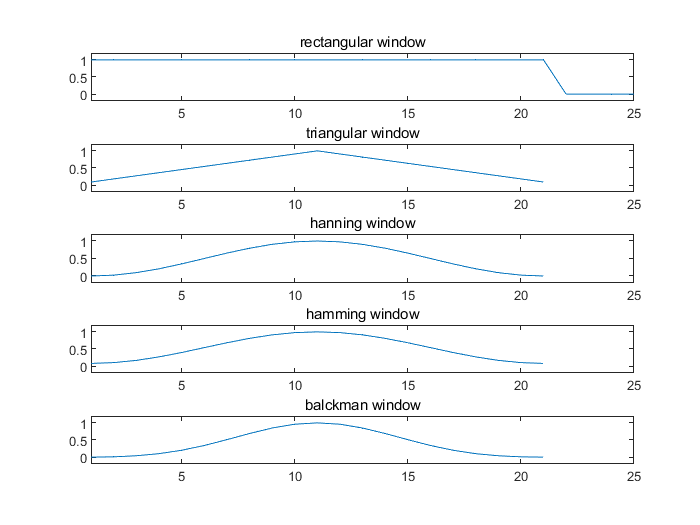

% question 1
clear;clc;close all;
figure()
subplot(5,1,1);plot([ones(1,21),0,0,0,0]);title('rectangular window');axis([1, 25,-0.2,1.2]);
subplot(5,1,2);plot(triang(21));title('triangular window');axis([1, 25,-0.2,1.2]);
subplot(5,1,4);plot(hamming(21));title('hamming window');axis([1, 25,-0.2,1.2]);
subplot(5,1,3);plot(hann(21));title('hanning window');axis([1, 25,-0.2,1.2]);
subplot(5,1,5);plot(blackman(21));title('balckman window');axis([1, 25,-0.2,1.2]);

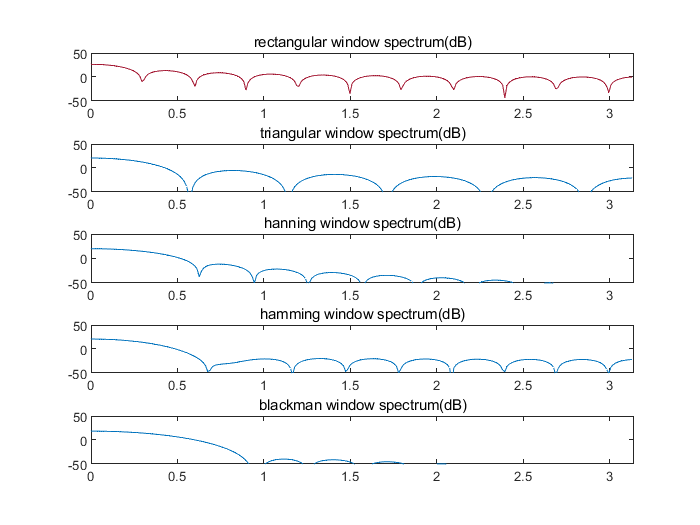


window1 = ones(21);
window2 = triang(21);
window3 = hann(21);
window4 = hamming(21);
window5 = blackman(21);
[H1, w1] = DTFT(window1,512);
[H2, w2] = DTFT(window2,512);
[H3, w3] = DTFT(window3,512);
[H4, w4] = DTFT(window4,512);
[H5, w5] = DTFT(window5,512);
H1 = 20*log10(abs(H1));
H2 = 20*log10(abs(H2));
H3 = 20*log10(abs(H3));
H4 = 20*log10(abs(H4));
H5 = 20*log10(abs(H5));
figure()
subplot(5,1,1);plot(w1,H1);title('rectangular window spectrum(dB)');axis([0,3.14,-50,50]);
subplot(5,1,2);plot(w2,H2);title('triangular window spectrum(dB)');axis([0,3.14,-50,50]);
subplot(5,1,3);plot(w3,H3);title('hanning window spectrum(dB)');axis([0,3.14,-50,50]);
subplot(5,1,4);plot(w4,H4);title('hamming window spectrum(dB)');axis([0,3.14,-50,50]);
subplot(5,1,5);plot(w5,H5);title('blackman window spectrum(dB)');axis([0,3.14,-50,50]);

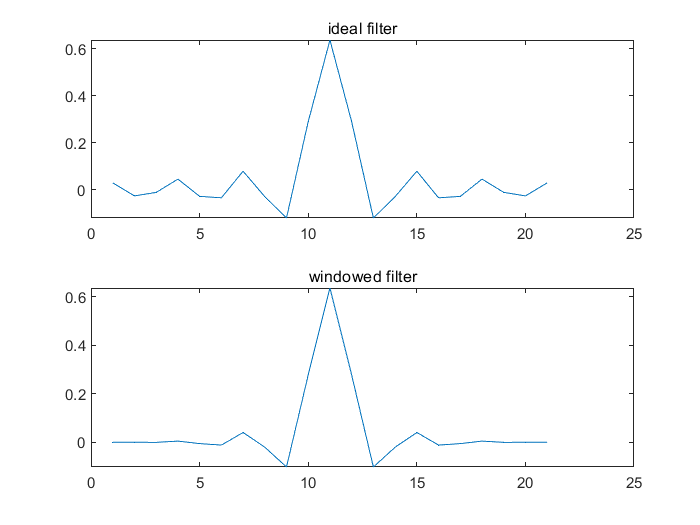



N = 21;
n = 0:N-1;
h_ideal = 2/pi*sinc(2/pi*(n-(N-1)/2));
h = h_ideal.*blackman(21)';
figure;
subplot(2,1,1);plot(h_ideal);title('ideal filter');
subplot(2,1,2);plot(h);title('windowed filter');

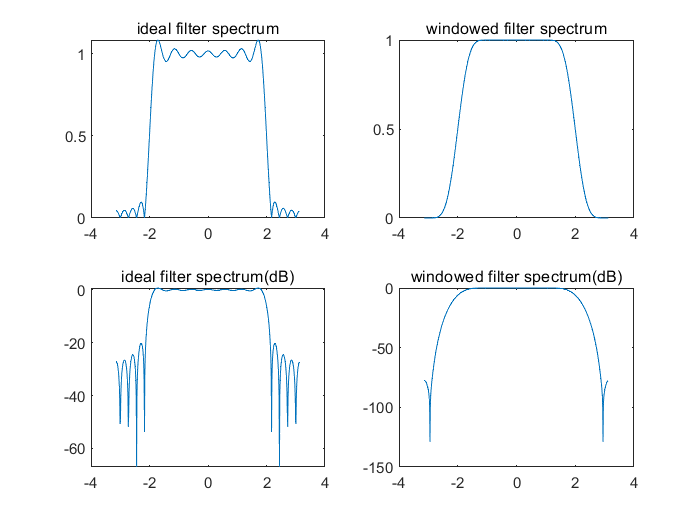


[H5, w5] = DTFT(h_ideal, 512);
[H6, w6] = DTFT(h, 512);
H5db = 20*log10(abs(H5));
H6db = 20*log10(abs(H6));
figure
subplot(2,2,1);plot(w5, abs(H5));title('ideal filter spectrum');
subplot(2,2,3);plot(w5, H5db);title('ideal filter spectrum(dB)');
subplot(2,2,2);plot(w6, abs(H6));title('windowed filter spectrum');
subplot(2,2,4);plot(w6, H6db);title('windowed filter spectrum(dB)');